## Logistic Map


$$X_{k+1} = \beta X_k (1-X_k) \\ 
\beta = 0 \ to \ 4 \\
X_0 = 0.5$$


clear all;close all; clc

xvals = [];

myVideo = VideoWriter("LogisticMap.mp4","MPEG-4")

myVideo =   VideoWriter

    General Properties:

       Filename:                 'LogisticMap.mp4'
       Path:                     'D:\AppliedMathStudy\Dynamic System\Logistic Map'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


myVideo.Quality = 100

myVideo =   VideoWriter

    General Properties:

       Filename:                 'LogisticMap.mp4'
       Path:                     'D:\AppliedMathStudy\Dynamic System\Logistic Map'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  100

  Methods


myVideo.FrameRate = 2;
open(myVideo)
figure('units','pixel','position',[0 0 1920 1080])
nit = 100

nit = 100

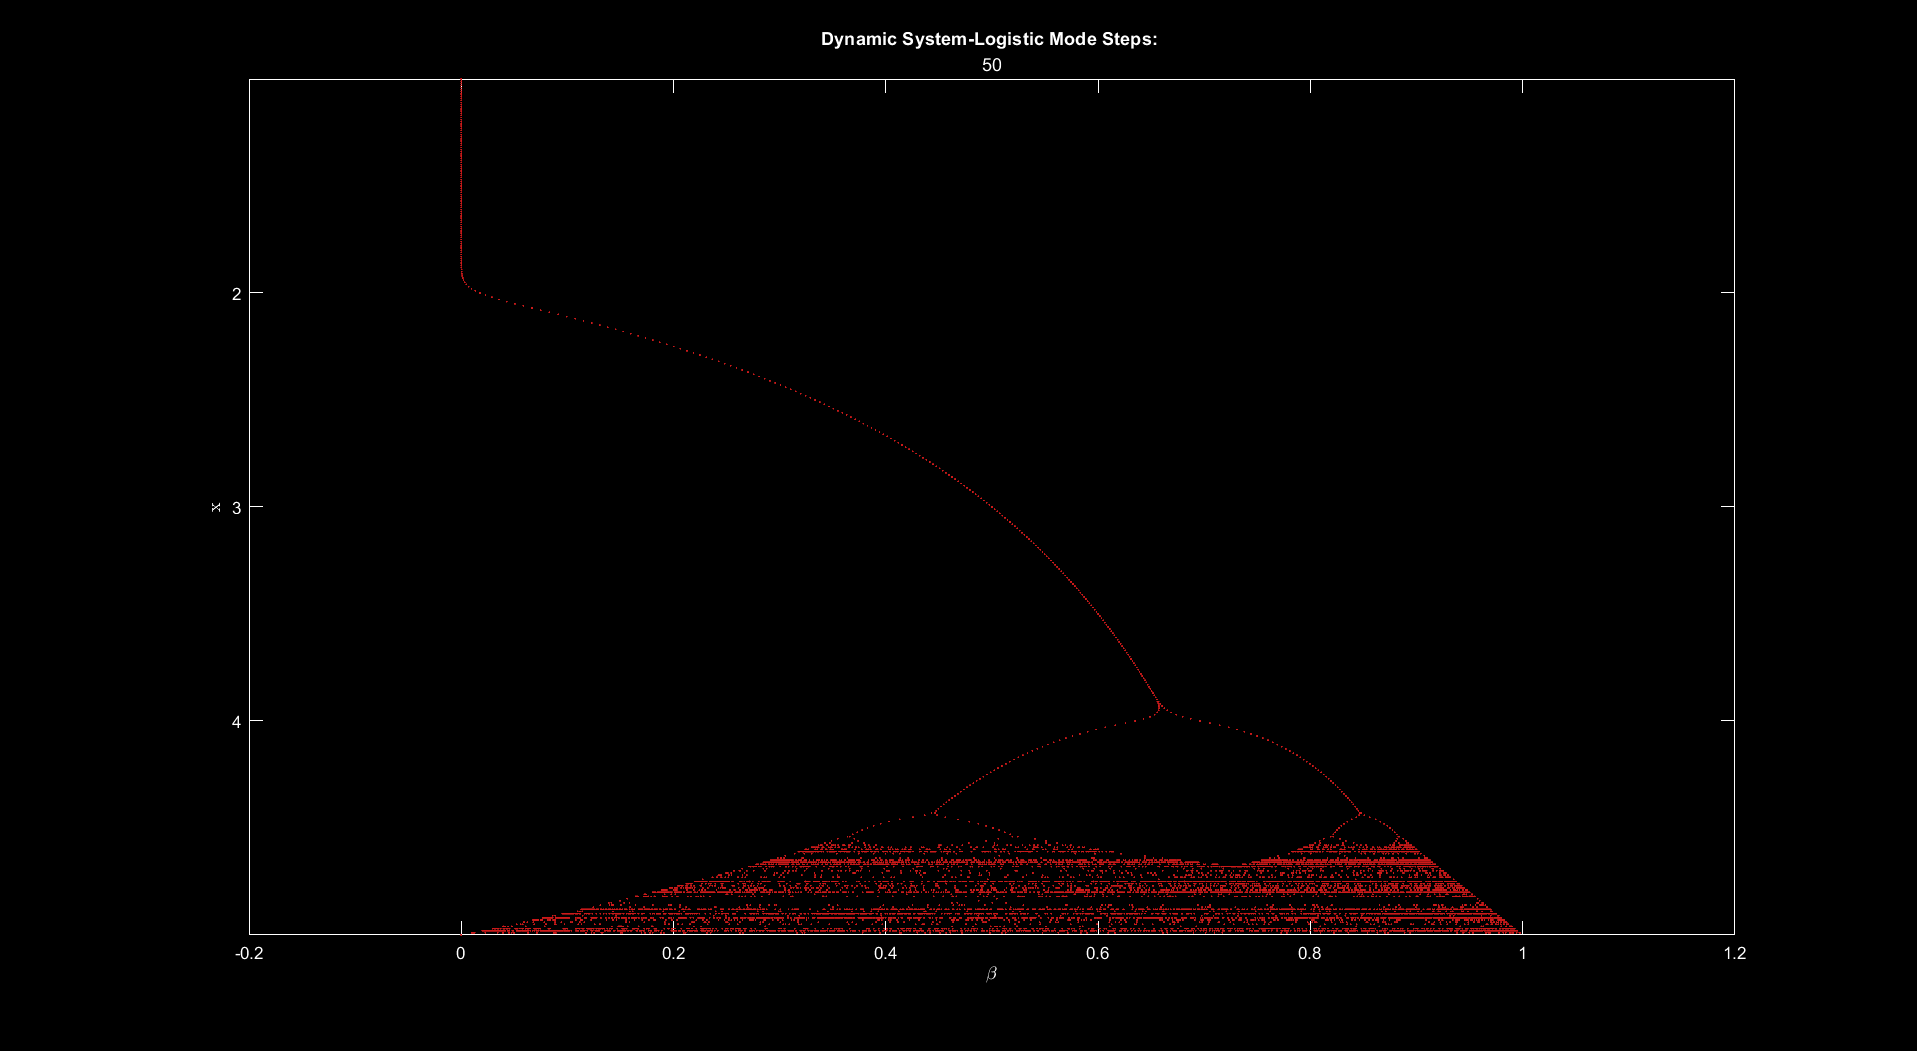

for k = 1:50
    xvals = [];
    for beta = 0:0.01:4
        beta;
        xold = 0.5;
        %transient
        for i = 1:k
            xnew = ((xold - xold^2)*beta);
            xold = xnew;
        end
        xss = xnew;
        for i = 1:1000
            xnew = ((xold - xold^2)*beta);
            xold = xnew;
            xvals(1,length(xvals)+1) = beta;
            xvals(2,length(xvals)) = xnew;
            if(abs(xnew-xss)<.001)
                break
            end
        end
    
    end
    
gcf;

plot(xvals(2,:),4-xvals(1,:),'.','LineWidth',.1,'MarkerSize',1.2,'Color',[.8 .1 .1])
set(gca,'color','k','xcolor','w','ycolor','w')
set(gcf,'color','k')
xlabel('$\beta$','Interpreter',"latex")
ylabel('x','Interpreter',"latex")
set(gca, 'YTick',[1 2 3 4],'YTickLabels',{'4','3','2',''})
title('Dynamic System-Logistic Mode Steps: ',num2str(k),'Color','W')
xlim([-0.2, 1.2])
pause(0.1)
frame = getframe(gcf);
writeVideo(myVideo,frame);
end

close(myVideo)

% exportgraphics(f,'Logistic Map.jpg','BackgroundColor',"black",'Resolution',500)